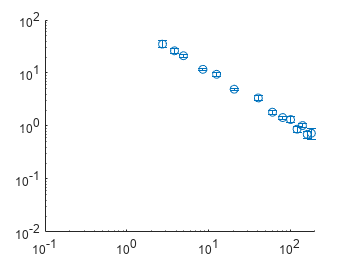

clear all
close all
colors=npg(100);
% Cat state Ramsey fringes
% Coherent state Ramsey fringes

main_dir='E:\Data\2022-12-10\Abs-4329';

f_sensitivity_coherent=openfig([main_dir,'\SensitivityDecay.fig']);

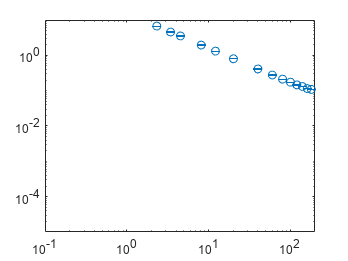


main_dir='E:\Data\2022-12-24\Abs-3551';

f_sensitivity_cat=openfig([main_dir,'\SensitivityDecay.fig']);



ax_1=get(f_sensitivity_cat,'CurrentAxes');
ax_2=get(f_sensitivity_coherent,'CurrentAxes');

ax_1_C=get(ax_1,'Children');
ax_2_C=get(ax_2,'Children');

figure_4=figure;
figure_4.Color='w';
figure_4.Units='inches';
figure_4.Position=[1 1 9 6];

ax1=axes;

hold on

g_I=0.27102;
nuclear_magneton=2*pi*7.6225932291*10^6;%Hz/T
gyro_factor=g_I*nuclear_magneton;


shaded_area_x=[0.001,0.001,500,500];
shaded_area_y=[1/0.001/(5)/(gyro_factor/10^9),1/0.001/sqrt(5)/(gyro_factor/10^9),1/500/sqrt(5)/(gyro_factor/10^9),1/500/(5)/(gyro_factor/10^9)];

SQL_HL_area=fill(shaded_area_x,shaded_area_y,colors(12,:))

SQL_HL_area =   Patch - 属性:

    FaceColor: [0.3020 0.7333 0.8353]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  显示 所有属性



shaded_area_y=[1/0.001/(5)/(gyro_factor/10^9),1e-5,1e-5,1/500/(5)/(gyro_factor/10^9)];
HL_area=fill(shaded_area_x,shaded_area_y,colors(12,:))

HL_area =   Patch - 属性:

    FaceColor: [0.3020 0.7333 0.8353]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  显示 所有属性



shaded_area_y=[1/0.001/sqrt(5)/(gyro_factor/10^9),1e5,1e5,1/500/sqrt(5)/(gyro_factor/10^9)];
SQL_area=fill(shaded_area_x,shaded_area_y,colors(12,:))

SQL_area =   Patch - 属性:

    FaceColor: [0.3020 0.7333 0.8353]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  显示 所有属性



HL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5)/(gyro_factor/10^9))

HL =   Line - 属性:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.0000e-03 0.1010 0.2010 0.3010 0.4010 0.5010 0.6010 0.7010 0.8010 0.9010 1.0010 1.1010 1.2010 1.3010 1.4010 1.5010 1.6010 1.7010 1.8010 1.9010 2.0010 2.1010 2.2010 2.3010 2.4010 2.5010 2.6010 2.7010 2.8010 2.9010 3.0010 3.1010 … ]
              YData: [1.5408e+04 152.5544 76.6567 51.1893 38.4239 30.7545 25.6373 21.9800 19.2359 17.1010 15.3926 13.9945 12.8293 11.8432 10.9979 10.2652 9.6240 9.0582 8.5552 8.1052 7.7001 7.3336 7.0005 6.6962 6.4173 6.1607 5.9239 5.7046 5.5009 … ]

  显示 所有属性


SQL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(sqrt(5))/(gyro_factor/10^9))

SQL =   Line - 属性:

              Color: [0.4660 0.6740 0.1880]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.0000e-03 0.1010 0.2010 0.3010 0.4010 0.5010 0.6010 0.7010 0.8010 0.9010 1.0010 1.1010 1.2010 1.3010 1.4010 1.5010 1.6010 1.7010 1.8010 1.9010 2.0010 2.1010 2.2010 2.3010 2.4010 2.5010 2.6010 2.7010 2.8010 2.9010 3.0010 3.1010 … ]
              YData: [3.4453e+04 341.1220 171.4095 114.4628 85.9185 68.7691 57.3267 49.1488 43.0129 38.2390 34.4189 31.2927 28.6872 26.4822 24.5919 22.9536 21.5199 20.2547 19.1301 18.1238 17.2180 16.3985 15.6535 14.9732 14.3496 13.7758 13.2462 … ]

  显示 所有属性


%mixed=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5/sqrt(16))/(1.298e-2))
mixed=plot(0.001:0.1:500,1./(0.001:0.1:500)*106.3,'--')

mixed =   Line - 属性:

              Color: [0.3010 0.7450 0.9330]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.0000e-03 0.1010 0.2010 0.3010 0.4010 0.5010 0.6010 0.7010 0.8010 0.9010 1.0010 1.1010 1.2010 1.3010 1.4010 1.5010 1.6010 1.7010 1.8010 1.9010 2.0010 2.1010 2.2010 2.3010 2.4010 2.5010 2.6010 2.7010 2.8010 2.9010 3.0010 3.1010 … ]
              YData: [106300 1.0525e+03 528.8557 353.1561 265.0873 212.1756 176.8719 151.6405 132.7091 117.9800 106.1938 96.5486 88.5096 81.7064 75.8744 70.8195 66.3960 62.4927 59.0228 55.9179 53.1234 50.5950 48.2962 46.1973 44.2732 42.5030 40.8689 … ]

  显示 

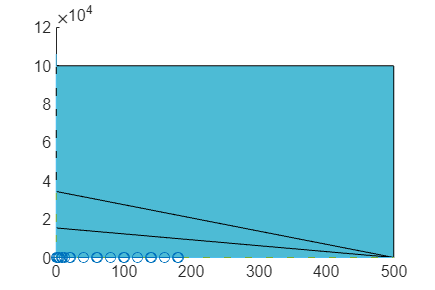


handle_1_cat=copyobj(ax_1_C, ax1);
handle_1_coherent=copyobj(ax_2_C, ax1);

% line color & width

HL.Color=colors(12,:);
SQL.Color=colors(65,:);
mixed.Color=colors(65,:);

HL.LineWidth=2;
SQL.LineWidth=2;
mixed.LineWidth=2;

% marker color
% handle_1_cat.SizeData=30;
% handle_1_coherent.SizeData=30;
% 
handle_1_cat.MarkerEdgeColor=colors(31,:);
handle_1_coherent.MarkerEdgeColor=colors(26,:);

handle_1_cat.MarkerFaceColor=colors(12,:);
handle_1_coherent.MarkerFaceColor=colors(65,:);

handle_1_cat.Color=colors(31,:);
handle_1_coherent.Color=colors(26,:);

handle_1_cat.LineWidth=1.5;
handle_1_coherent.LineWidth=1.5;

handle_1_cat.CapSize=0;
handle_1_coherent.CapSize=0;

handle_1_cat.MarkerSize=8;
handle_1_coherent.MarkerSize=8;


%shaded area

SQL_HL_area.FaceAlpha=0.3;
SQL_HL_area.EdgeColor='none';
SQL_HL_area.FaceColor=colors(12,:);

HL_area.FaceAlpha=0.6;
HL_area.EdgeColor='none';
HL_area.FaceColor=colors(9,:);

SQL_area.FaceAlpha=0.3;
SQL_area.EdgeColor='none';
SQL_area.FaceColor=colors(65,:);

% axis limits & scales


ax1.XLim=[1 300];
ax1.YLim=[6e-2 1.05e2];


set(ax1,'YScale','log')
set(ax1,'XScale','log')

% axis labels

xlabel(ax1,'Interrogation time s')
xlabel(ax1,'$\mathrm{Interrogation\ time,}\ \tau\ \mathrm{(s)}$','Interpreter','latex','FontName','Times New Roman','FontSize',20)


ylabel(ax1,'Sensitivity (nT)')


% axis fonts
ax1.FontSize=20;

ax1.FontName='Times New Roman';


ax1.Box='on';

legend1=legend([handle_1_coherent,handle_1_cat],{'Coherent spin state','Cat state'},'Box','off','Location','northeast')

legend1 =   Legend (Coherent spin state, Cat state) - 属性:

         String: {'Coherent spin state'  'Cat state'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 18
       Position: [0.6208 0.8053 0.2720 0.1016]
          Units: 'normalized'

  显示 所有属性


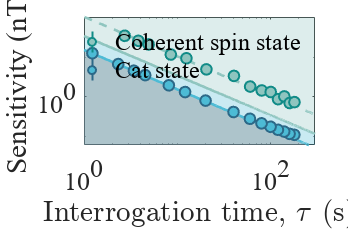

legend1 =   Legend (Coherent spin state, Cat state) - 属性:

         String: {'Coherent spin state'  'Cat state'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 18
       Position: [0.6208 0.8053 0.2720 0.1016]
          Units: 'normalized'

  显示 所有属性


%ah=axes('position',get(gca,'Position'),'Visible','off')
%legend2=legend(ah,[SQL,HL],'Standard quantum limit','Heisenberg limit','Box','off','Location','northeast')
%legend('Boxoff')

%ah.FontSize=14;
%ah.FontName='Times New Roman';


legend1.Color='none'

%legend2.Color='none'

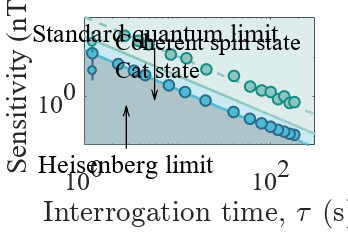

annotation(figure_4,'textarrow',[0.444340277777777,0.444340277777777],[0.79470486111111,0.568142361111109],...
    'VerticalAlignment','bottom',...
    'String',{'Standard quantum limit'},...
    'LineWidth',1,...
    'HorizontalAlignment','center',...
    'HeadWidth',6,...
    'HeadStyle','vback3',...
    'HeadLength',8,...
    'FontSize',20,...
    'FontName','Times New Roman');

% 创建 textarrow
annotation(figure_4,'textarrow',[0.36290509259259,0.36290509259259],...
    [0.359270833333333,0.544270833333333],'String',{'Heisenberg limit'},...
    'LineWidth',1,...
    'HorizontalAlignment','center',...
    'HeadWidth',6,...
    'HeadStyle','vback3',...
    'HeadLength',8,...
    'FontSize',20,...
    'FontName','Times New Roman');

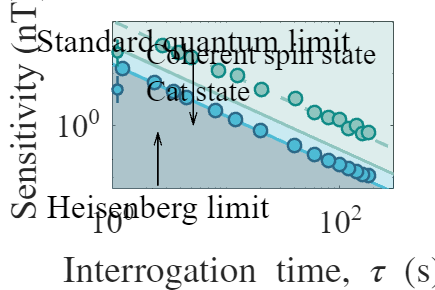

print(figure_4, ['\\Artemis-pc\e\Data\DataForPub','\Figure4.png'],'-r600','-dpng');
hgexport(figure_4, ['\\Artemis-pc\e\Data\DataForPub','\Figure4.eps'])